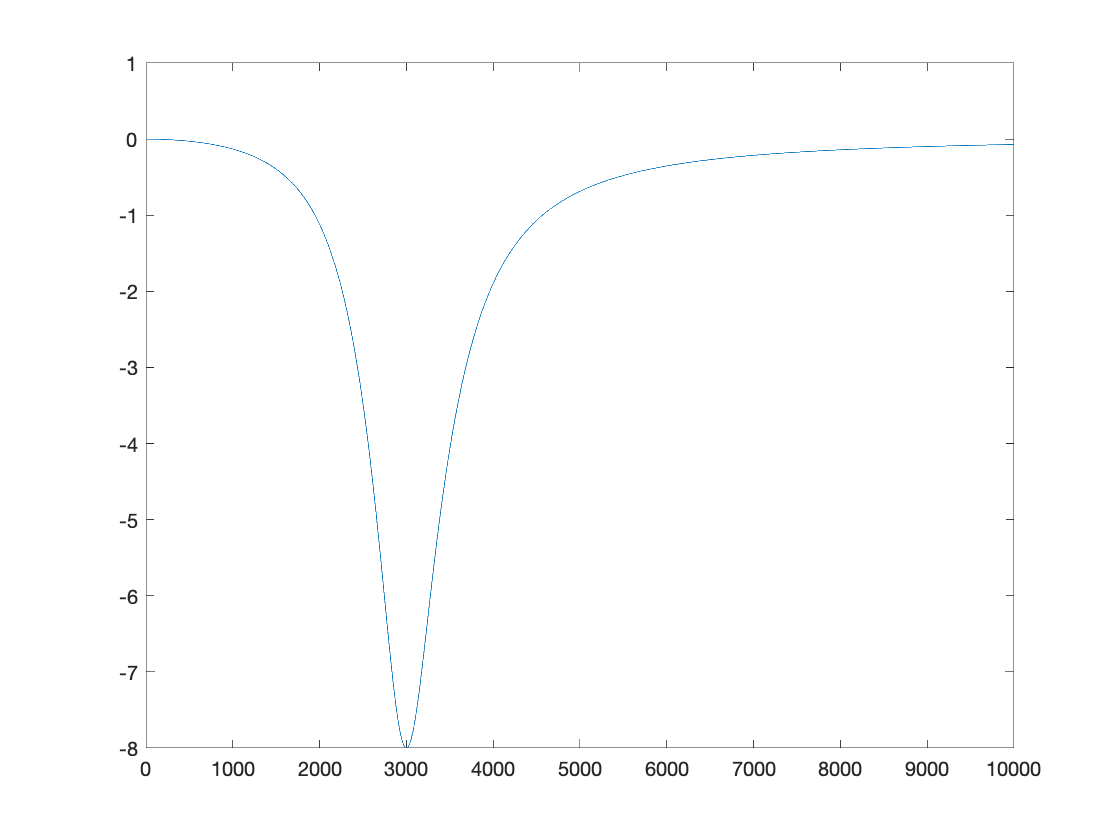

% From Välimäki, Vesa, Bo Holm-Rasmussen, Benoit Alary, and Heidi-Maria Lehtonen. “Late Reverberation Synthesis Using Filtered Velvet Noise.” Applied Sciences 7, no. 5 (May 6, 2017): 483. https://doi.org/10.3390/app7050483.

fs = 44100;
fb = 600;
fc = 3000;
V0db = -8;
V0 = db2mag(V0db);

tanfb = tan(pi*fb/fs);
c = (tanfb-V0) / (tanfb+V0);
d = -cos(2*pi*fc/fs);

A2b = [-c d*(1-c) 1];
A2a = [1 d*(1-c) -c];

% A2b = 1 + (V0-1) * (1 - A2b)
% A2a = 1 + 2 * (1 - A2b)
% [H, w] = freqz(A2b, A2a, 512);

G = V0 - 1;
Gp2 = G + 2;
% b = [ ...
%     Gp2*A2a(1) - G*A2b(1), ...
%     Gp2*A2a(2) - G*A2b(2), ...
%     Gp2*A2a(3) - G*A2b(3), ...
% ];
b = (G + 2)*A2a - G*A2b;
a = 2 * A2a;

[H, w] = freqz(b, a, 2^14);

% semilogx(w*fs/(2*pi), mag2db(abs(H)))
plot(w*fs/(2*pi), mag2db(abs(H))); xlim([0, 10e3])